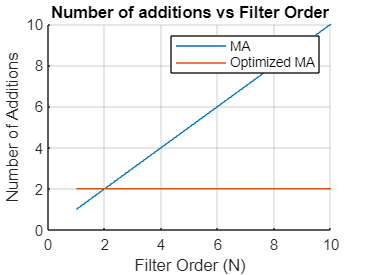

% Moving_Average_Filter
clear all;
close all;
clc;

N = 1:10;

% array for storing the number of additions
Additions_MA = zeros(size(N));
 
% Moving Average filter
for i = 1: length(N)
    Additions_MA(i) = N(i);
end

% Optimized Moving Average filter.
Additions_OMA = 2 * ones(size(N)); 

% Plot the results
figure;
hold on;
plot (N, Additions_MA);
plot (N, Additions_OMA);

xlabel ('Filter Order (N)');
ylabel ('Number of Additions');
legend('MA','Optimized MA');
title ('Number of additions vs Filter Order');
grid on;
hold off;